clc
clear all
close all
addpath("functions")

## **1. GP complexity**

This section of the code is dedicated to answering question 3.1 and all its 5 sub-questions.

%Assigning given values
hyp = [0.05;1]; %defining hyper parameters
Nd = [10 15 20 22];%different Nd values for data generation
N = Nd.^3;

#### Testing GPregression for differently sized data sets

j_lim = 10;
i_lim = length(Nd);

% Preallocate matrices for the times
elapsed_times = zeros(j_lim, i_lim);
inverse_times = zeros(j_lim, i_lim);
mean_times = zeros(j_lim, i_lim);
covariance_times = zeros(j_lim, i_lim);
pre_allocation_times = zeros(j_lim, i_lim);

for j = 1:j_lim
    for i = 1:i_lim  %Second for loop for each dataset with a different Nd value.
        %generate dataset
        [X, y, Xstar] = getdata(Nd(i), hyp);
        if Nd(i) == 10 && i==1 && j==1
            X1 = X;
            y1 = y;
            Xstar1 = Xstar;
        end
    
        %Perform GP regression, time it and calculate the models mean and covariance for
        %new points and kernel matrix for training points.
        function_timer = tic;
        [GPmean, GPcov, k_matrix, inverse_time, mean_time, covariance_time, pre] = GPregression(X, y, Xstar, hyp);
        elapsed_time = toc(function_timer);
    
        %separate line in order to calculate average elapsed time later on
        %in the code
        elapsed_times(j,i) = elapsed_time;
        inverse_times(j,i) = inverse_time;
        mean_times(j,i) = mean_time;
        covariance_times(j,i) = covariance_time;
        pre_allocation_times(j,i) = pre;
    
        %Save relevantdata in results parameter.
        %results.GPmodel = GPmodel;
        %results.predictions = predictions;
        results.mean = GPmean;
        results.cov = GPcov;
        results.k_matrix = k_matrix;
        results.elapsed_time = elapsed_time;
        results.Nd = Nd(i);
    
        %extra output to find the time
        results.inverse_time = inverse_time; 
        results.mean_time =  mean_time; 
        results.covariance_time =  covariance_time;
        results.pre_allocation_time = pre;
    
        %allocate output of the model
        GP_data{j,i} = results;
    end
end


% Calculate the average elapsed time per Nd value
average_elapsed_time = mean(elapsed_times, 1);
average_inverse_time = mean(inverse_times, 1);
average_mean_time = mean(mean_times, 1);
average_covariance_time = mean(covariance_times, 1);
average_pre_allocation_time = mean(pre_allocation_times, 1);

% Display the average elapsed times
for i = 1:i_lim
    fprintf('___----=====Now looking at Nd = %d=====----___', Nd(i));
    fprintf('Average inverse time for Nd = %d: %.4f seconds\n', Nd(i), average_inverse_time(i));
    fprintf('Average pre-allocation time for Nd = %d: %.4f seconds\n', Nd(i), average_pre_allocation_time(i));
    fprintf('Average mean time for Nd = %d: %.4f seconds\n', Nd(i), average_mean_time(i));
    fprintf('Average covariance time for Nd = %d: %.4f seconds\n', Nd(i), average_covariance_time(i));
    fprintf('Average elapsed time for Nd = %d: %.4f seconds\n', Nd(i), average_elapsed_time(i));
end

___----=====Now looking at Nd = 10=====----___

Average inverse time for Nd = 10: 0.0941 seconds


Average pre-allocation time for Nd = 10: 0.0376 seconds


Average mean time for Nd = 10: 0.0020 seconds


Average covariance time for Nd = 10: 0.0710 seconds


Average elapsed time for Nd = 10: 2.4328 seconds


___----=====Now looking at Nd = 15=====----___

Average inverse time for Nd = 15: 1.3382 seconds


Average pre-allocation time for Nd = 15: 0.6937 seconds


Average mean time for Nd = 15: 0.0090 seconds


Average covariance time for Nd = 15: 0.7451 seconds


Average elapsed time for Nd = 15: 3.6614 seconds


___----=====Now looking at Nd = 20=====----___

Average inverse time for Nd = 20: 12.7873 seconds


Average pre-allocation time for Nd = 20: 8.7027 seconds


Average mean time for Nd = 20: 0.0438 seconds


Average covariance time for Nd = 20: 8.6956 seconds


Average elapsed time for Nd = 20: 34.0161 seconds


___----=====Now looking at Nd = 22=====----___

Average inverse time for Nd = 22: 32.7194 seconds


Average pre-allocation time for Nd = 22: 14.8899 seconds


Average mean time for Nd = 22: 0.0588 seconds


Average covariance time for Nd = 22: 14.0155 seconds


Average elapsed time for Nd = 22: 67.8464 seconds


#### Plotting 3D results for N=1000

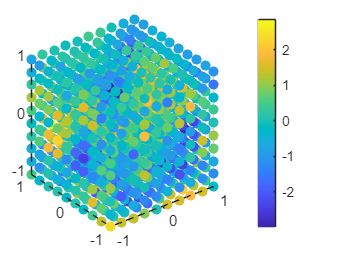

%Getting predictions of model for Nd = 10
%preds = GP_data{1}.predictions;
preds = GP_data{1}.mean;

[X1, y1, Xstar1] = getdata(10, hyp);

%3D scatterplot of data + colorbar
scatter3(X1(:,1),X1(:,2),X1(:,3),[],y1,'filled')
colorbar;

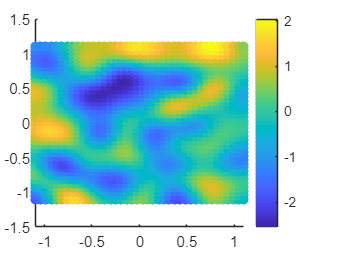


%Scatterplot of predictions
scatter(Xstar1(:,1),Xstar1(:,3),[],preds,'filled')
colorbar;

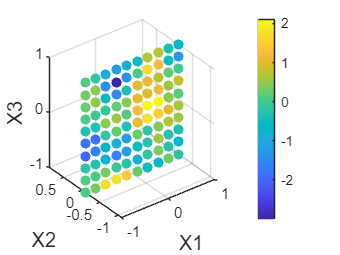


% Get data for X2 is -1/9 and 1/9
X2_neg_part = find(X1(:, 2) == -1/9);
X2_pos_part = find(X1(:, 2) == 1/9);

scatter3(X1(X2_neg_part, 1), X1(X2_neg_part, 2), X1(X2_neg_part, 3), [], y1(X2_neg_part), 'filled')    % y1?
xlabel('X1', 'FontSize', 12);
ylabel('X2', 'FontSize', 12);
zlabel('X3', 'FontSize', 12);
colorbar;

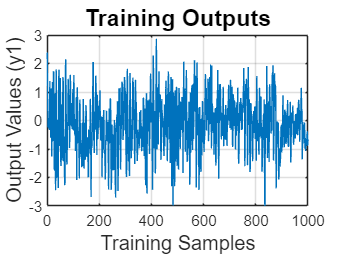


% scatter(X1(X2_neg_part, 1), X1(X2_neg_part, 3), [], y1(X2_neg_part), 'filled')    % y1?
% xlabel('X1', 'FontSize', 12);
% ylabel('X3', 'FontSize', 12);
% colorbar;

%Additional plots to understand the data and for the report
figure; %Output data plot
plot(y1); 
title('Training Outputs', 'FontSize', 14);
xlabel('Training Samples', 'FontSize', 12);
ylabel('Output Values (y1)', 'FontSize', 12);
grid on;

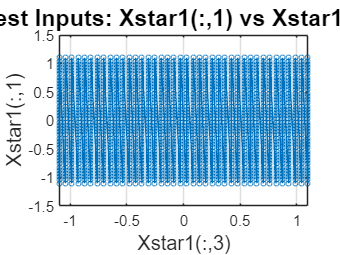


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), Xstar1(:,1),'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) vs Xstar1(:,3)', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('Xstar1(:,1)', 'FontSize', 12); 
grid on;  

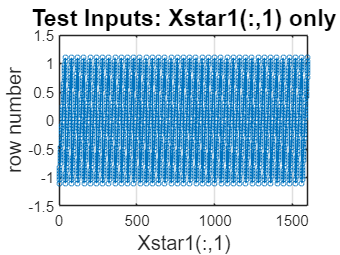


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,1), 'o-',  'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) only', 'FontSize', 14);
xlabel('Xstar1(:,1)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;  

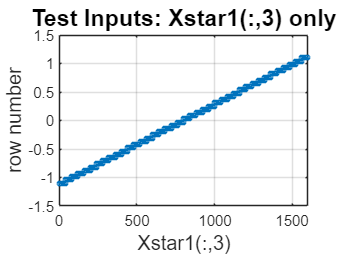


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), 'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,3) only', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;

## 2. Kernel Matrix as Tensor Train

K = GP_data{1}.k_matrix;        %Kernel matrix for 10^3 inputs.
I = [10 10 10]; J = [10 10 10]; %Given size dimensions
eps = 1e-10;                    %Given epsilon value

%reshaping matrix into tensor in order to make it ready for TT_SVD
K_tensor = reshape(K,[I, J]);
K_tensor1 = permute(K_tensor,[1,4,2,5,3,6]);
K_tensor2 = reshape(K_tensor1,I(1)*J(1),I(2)*J(2),I(3)*J(3));

%Turning the tensor into a tensor train.
[tt_K1,rel_err1] = TT_SVD(K_tensor1,eps);
[tt_K2,rel_err2] = TT_SVD(K_tensor2,eps);

%calculating the compression ratio
num_el_tt1 = TT_numel(tt_K1);
num_el_tt2 = TT_numel(tt_K2);

fprintf("the number of elements of the first tensor train is %d and of the 2nd tensor train %d",num_el_tt1,num_el_tt2);

the number of elements of the first tensor train is 600 and of the 2nd tensor train 300

numel_k = numel(K);
comp_ratio1 = num_el_tt1/numel_k

comp_ratio1 = 6.0000e-04

comp_ratio2 = num_el_tt2/numel_k

comp_ratio2 = 3.0000e-04


Ranks_tt_K1 = TT_get_ranks(tt_K1)

Ranks_tt_K1 =      1
    10
     1
    10
     1
    10
     1


Ranks_tt_K2 = TT_get_ranks(tt_K2)

Ranks_tt_K2 =      1
     1
     1
     1


## 3. Kernel Matrix as Kronecker Product

This section of the matlab code is dedicated to answering question 3 of the assignment.

## Validation

%Defining points in 3D space
%Choice of Nd value, you can change this part of the code
Ndc = 10;

The rest of this section is just checking whether the kronecker algebra and kron_mvprod/kron_mmprod functions all work accordingly

%Calculating the kernel matrix (same as the GPregression algorithm) for
%comparisons and validations
joint_kernel_matrix = kernel_matrix([X1; Xstar1], hyp(1), hyp(2));
N_X = size(X1,1);

%Generating dataset
[X1, y1, Xstar1] = getdata(Ndc, hyp);

%sub-dividing the joint kernel matrix in its respective parts
K = joint_kernel_matrix(1:N_X,1:N_X);   % we don't remove this, as we want to test the speedup of the inverse
K_X_Xstar = joint_kernel_matrix(1:N_X,N_X+1:end);
K_Xstar_X = K_X_Xstar.';
K_Xstar_Xstar = joint_kernel_matrix(N_X+1:end, N_X+1:end);

x1 = linspace(-1,1,Ndc)';
x2 = linspace(-1,1,Ndc)';
x3 = linspace(-1,1,Ndc)';
[X1, y1, Xstar1] = getdata(Ndc, hyp);
I = [Ndc Ndc Ndc]; J = [Ndc Ndc Ndc];
mat_size = [Ndc^3 Ndc^3];

%calculating Kernel matrices per dimension.
K1 = kernel_matrix_dimension(x1, hyp(1), hyp(2));
K2 = kernel_matrix_dimension(x2, hyp(1), hyp(2));
K3 = kernel_matrix_dimension(x3, hyp(1), hyp(2));

%Calculating kronecker product of
K_kron = kron(K3,kron(K2,K1));

%veryfying whether it's the same
norm(K-K_kron,'fro')

ans = 3.8365e-14

assert(norm(K-K_kron,'fro') < 1e-8,'Kronecker kernel matrix not equal to non-Kronecker kernel matrix')

%Testing whether kronecker inverse is same as actual inverse
K_test_inv = kron(inv(K3),kron(inv(K2),inv(K1)));
norm(K_test_inv-inv(K) ,'fro')

ans = 9.1868e+07

%assert(norm(K_test_inv-inv(K) ,'fro') < 1e-8,'Kronecker inverse kernel matrix not equal to non-Kronecker inverse kernel matrix')
norm(K_test_inv - inv(K_kron),'fro')

ans = 3.1318e+07

%assert(norm(K_test_inv-inv(K_kron) ,'fro') < 2e-8,'Kronecker inverse kernel matrix not equal to inversion of kronecker product matrix')

%Turning kronecker product into tensor train
tt_test{1} = reshape(K3,1,[],1);
tt_test{2} = reshape(K2,1,[],1);
tt_test{3} = reshape(K1,1,[],1);
tt_test{4} = 0;

%Rebuilding tensor from tensor train
Ktensor_tt_test = TT_reconstruct(tt_test);
Ktensor_tt_test = reshape(Ktensor_tt_test,[I,J]);
Ktensor_tt_test = permute(Ktensor_tt_test,[1 3 5 2 4 6]);
Kmat_tt_test = reshape(Ktensor_tt_test,mat_size);

norm(K_kron-Kmat_tt_test,'fro')

ans = 0

assert(norm(K_kron-Kmat_tt_test,'fro') < 1e-8,'Kronecker product not equal to tensor train product')

norm(K-Kmat_tt_test,'fro')

ans = 3.8365e-14

assert(norm(K-Kmat_tt_test,'fro') < 1e-8,'matrix not equal to tensor train product')

%Now saving inverse as TT product and checking same stuff as before.
tt_inv_test{1} = reshape(inv(K3),1,[],1);
tt_inv_test{2} = reshape(inv(K2),1,[],1);
tt_inv_test{3} = reshape(inv(K1),1,[],1);
tt_inv_test{4} = 0;

%Rebuilding tensor from tensor train
Ktensor_tt_inv_test = TT_reconstruct(tt_inv_test);
Ktensor_tt_inv_test = reshape(Ktensor_tt_inv_test,[I,J]);
Ktensor_tt_inv_test = permute(Ktensor_tt_inv_test,[1 3 5 2 4 6]);
Kmat_tt_inv_test = reshape(Ktensor_tt_inv_test,mat_size);

norm(K_test_inv-Kmat_tt_inv_test,'fro')

ans = 0

assert(norm(K_kron-Kmat_tt_test,'fro') < 1e-8,'Kronecker product not equal to tensor train product')

norm(inv(K)-Kmat_tt_inv_test,'fro')

ans = 9.1868e+07

%assert(norm(inv(K)-Kmat_tt_inv_test,'fro') < 1e-9,'matrix not equal to tensor train product')

%Another check for the kron_mvprod and kron_mmprod functions

v1 = K*y1;
v2 = kron_mvprod({K3,K2,K1},y1);
err_mv = norm(v1-v2,'fro')

err_mv = 2.8104e-12

assert(err_mv < 1e-8, "error of kron_mvprod is not small enough")

V1 = K\K_X_Xstar;
V2 = kron_mmprod({K3,K2,K1},K_X_Xstar);
err_mm = norm(V1-V2,'fro')

err_mm = 0.0115

%assert(err_mm < 1e-8, "error of kron_mmprod is not small enough")

Test_Kmat = kron_mmprod({K3,K2,K1},K_X_Xstar);

norm(Test_Kmat - K\K_X_Xstar,'fro')

ans = 0.0115

## 4. GP's with Tensor Train

## Inverse optimization ONLY

%j_lim = 3;
%i_lim = length(Nd);

% Preallocate matrices for the times
elapsed_times = zeros(j_lim, i_lim);
inverse_times = zeros(j_lim, i_lim);
mean_times = zeros(j_lim, i_lim);
covariance_times = zeros(j_lim, i_lim);
pre_allocation_times = zeros(j_lim, i_lim);

for j = 1:j_lim
    for i = 1:i_lim  %Second for loop for each dataset with a different Nd value.
        %generate dataset
        [X, y, Xstar] = getdata(Nd(i), hyp);
        if Nd(i) == 10 && i == 1 && j == 1
            X1 = X;
            y1 = y;
            Xstar1 = Xstar;
        end
        %Calculating K1, K2 and K3
        x1 = linspace(-1,1,Nd(i))'; x2 = linspace(-1,1,Nd(i))'; x3 = linspace(-1,1,Nd(i))';
        K1 = kernel_matrix_dimension(x1, hyp(1), hyp(2));
        K2 = kernel_matrix_dimension(x2, hyp(1), hyp(2));
        K3 = kernel_matrix_dimension(x3, hyp(1), hyp(2));

        %Perform GP regression, time it and calculate the models mean and covariance for
        %new points and kernel matrix for training points.
        function_timer = tic;
        [GPmean, GPcov, k_matrix, inverse_time, mean_time, covariance_time, pre] = KronGPregression(K1, K2, K3, X, y, Xstar, hyp);
        elapsed_time = toc(function_timer);

        %separate line in order to calculate average elapsed time later on
        %in the code
        kron_elapsed_times(j,i) = elapsed_time;
        kron_inverse_times(j,i) = inverse_time;
        kron_mean_times(j,i) = mean_time;
        kron_covariance_times(j,i) = covariance_time;
        kron_pre_allocation_times(j,i) = pre;
    
        %Save relevantdata in results parameter.
        %results.GPmodel = GPmodel;
        %results.predictions = predictions;
        results.mean = GPmean;
        results.cov = GPcov;
        results.k_matrix = k_matrix;
        results.elapsed_time = elapsed_time;
        results.Nd = Nd(i);
    
        %extra output to find the time
        results.inverse_time = inverse_time; 
        results.mean_time =  mean_time; 
        results.covariance_time =  covariance_time;
        results.pre_allocation_time = pre;
    
        %allocate output of the model
        KronGP_data{j,i} = results;
        assert(norm(k_matrix-GP_data{j,i}.k_matrix,'fro') < 1e-9,'Kroncker kernel matrix not equal to original kernel matrix');
    end
end

% Calculate the average elapsed time per Nd value
average_elapsed_time = mean(kron_elapsed_times, 1);
average_inverse_time = mean(kron_inverse_times, 1);
average_mean_time = mean(kron_mean_times, 1);
average_covariance_time = mean(kron_covariance_times, 1);
average_pre_allocation_time = mean(kron_pre_allocation_times, 1);

% Display the average elapsed times
for i = 1:i_lim
    fprintf('___----=====Now looking at Nd = %d=====----___', Nd(i));
    fprintf('Average inverse time for Nd = %d: %.4f seconds\n', Nd(i), average_inverse_time(i));
    fprintf('Average pre-allocation time for Nd = %d: %.4f seconds\n', Nd(i), average_pre_allocation_time(i));
    fprintf('Average mean time for Nd = %d: %.4f seconds\n', Nd(i), average_mean_time(i));
    fprintf('Average covariance time for Nd = %d: %.4f seconds\n', Nd(i), average_covariance_time(i));
    fprintf('Average elapsed time for Nd = %d: %.4f seconds\n', Nd(i), average_elapsed_time(i));
end

___----=====Now looking at Nd = 10=====----___

Average inverse time for Nd = 10: 0.0044 seconds


Average pre-allocation time for Nd = 10: 0.0397 seconds


Average mean time for Nd = 10: 0.0015 seconds


Average covariance time for Nd = 10: 0.0601 seconds


Average elapsed time for Nd = 10: 0.2182 seconds


___----=====Now looking at Nd = 15=====----___

Average inverse time for Nd = 15: 0.0288 seconds


Average pre-allocation time for Nd = 15: 0.6230 seconds


Average mean time for Nd = 15: 0.0102 seconds


Average covariance time for Nd = 15: 0.7373 seconds


Average elapsed time for Nd = 15: 2.0518 seconds


___----=====Now looking at Nd = 20=====----___

Average inverse time for Nd = 20: 0.1459 seconds


Average pre-allocation time for Nd = 20: 6.6387 seconds


Average mean time for Nd = 20: 0.0329 seconds


Average covariance time for Nd = 20: 4.9657 seconds


Average elapsed time for Nd = 20: 14.3724 seconds


___----=====Now looking at Nd = 22=====----___

Average inverse time for Nd = 22: 2.3578 seconds


Average pre-allocation time for Nd = 22: 16.5256 seconds


Average mean time for Nd = 22: 0.0867 seconds


Average covariance time for Nd = 22: 10.6367 seconds


Average elapsed time for Nd = 22: 38.7721 seconds


## Combination of all optimizations

% Preallocate matrices for the times
elapsed_times = zeros(j_lim, i_lim);
inverse_times = zeros(j_lim, i_lim);
mean_times = zeros(j_lim, i_lim);
covariance_times = zeros(j_lim, i_lim);
pre_allocation_times = zeros(j_lim, i_lim);

for j = 1:j_lim
    for i = 1:i_lim  %Second for loop for each dataset with a different Nd value.
        %generate dataset
        [X, y, Xstar] = getdata(Nd(i), hyp);
        if Nd(i) == 10 && i == 1 && j == 1
            X1 = X;
            y1 = y;
            Xstar1 = Xstar;
        end
        %Calculating K1, K2 and K3
        x1 = linspace(-1,1,Nd(i))'; x2 = linspace(-1,1,Nd(i))'; x3 = linspace(-1,1,Nd(i))';
        K1 = kernel_matrix_dimension(x1, hyp(1), hyp(2));
        K2 = kernel_matrix_dimension(x2, hyp(1), hyp(2));
        K3 = kernel_matrix_dimension(x3, hyp(1), hyp(2));

        %Perform GP regression, time it and calculate the models mean and covariance for
        %new points and kernel matrix for training points.
        function_timer = tic;
        [GPmean, GPcov, k_matrix, inverse_time, mean_time, covariance_time, pre] = KronGPregression2(K1, K2, K3, X, y, Xstar, hyp);
        elapsed_time = toc(function_timer);

        %separate line in order to calculate average elapsed time later on
        %in the code
        kron_elapsed_times(j,i) = elapsed_time;
        kron_inverse_times(j,i) = inverse_time;
        kron_mean_times(j,i) = mean_time;
        kron_covariance_times(j,i) = covariance_time;
        kron_pre_allocation_times(j,i) = pre;
    
        %Save relevantdata in results parameter.
        %results.GPmodel = GPmodel;
        %results.predictions = predictions;
        results.mean = GPmean;
        results.cov = GPcov;
        results.k_matrix = k_matrix;
        results.elapsed_time = elapsed_time;
        results.Nd = Nd(i);
    
        %extra output to find the time
        results.inverse_time = inverse_time; 
        results.mean_time =  mean_time; 
        results.covariance_time =  covariance_time;
        results.pre_allocation_time = pre;
    
        %allocate output of the model
        KronGP_data2{j,i} = results;
        assert(norm(k_matrix-GP_data{j,i}.k_matrix,'fro') < 1e-9,'Kroncker kernel matrix not equal to original kernel matrix');

        %Extra test to verify whether M << N holds
        joint_kernel_matrix = kernel_matrix([X; Xstar], hyp(1), hyp(2));
        K_X_Xstar = joint_kernel_matrix(1:Nd(i)^3,Nd(i)^3+1:end);
        [Ns(i),Ms(i)] = size(K_X_Xstar);
    end
end

% Calculate the average elapsed time per Nd value
average_elapsed_time = mean(kron_elapsed_times, 1);
average_inverse_time = mean(kron_inverse_times, 1);
average_mean_time = mean(kron_mean_times, 1);
average_covariance_time = mean(kron_covariance_times, 1);
average_pre_allocation_time = mean(kron_pre_allocation_times, 1);

% Display the average elapsed times
for i = 1:i_lim
    fprintf('___----=====Now looking at Nd = %d=====----___', Nd(i));
    fprintf('Average inverse time for Nd = %d: %.4f seconds\n', Nd(i), average_inverse_time(i));
    fprintf('Average pre-allocation time for Nd = %d: %.4f seconds\n', Nd(i), average_pre_allocation_time(i));
    fprintf('Average mean time for Nd = %d: %.4f seconds\n', Nd(i), average_mean_time(i));
    fprintf('Average covariance time for Nd = %d: %.4f seconds\n', Nd(i), average_covariance_time(i));
    fprintf('Average elapsed time for Nd = %d: %.4f seconds\n', Nd(i), average_elapsed_time(i));
    fprintf('M = %d and N = %d:', Ms(i), Ns(i));
end

___----=====Now looking at Nd = 10=====----___

Average inverse time for Nd = 10: 0.0000 seconds


Average pre-allocation time for Nd = 10: 0.0000 seconds


Average mean time for Nd = 10: 0.0024 seconds


Average covariance time for Nd = 10: 0.1376 seconds


Average elapsed time for Nd = 10: 0.2166 seconds


M = 1600 and N = 1000:

___----=====Now looking at Nd = 15=====----___

Average inverse time for Nd = 15: 0.0000 seconds


Average pre-allocation time for Nd = 15: 0.0000 seconds


Average mean time for Nd = 15: 0.0069 seconds


Average covariance time for Nd = 15: 1.2552 seconds


Average elapsed time for Nd = 15: 1.7392 seconds


M = 3600 and N = 3375:

___----=====Now looking at Nd = 20=====----___

Average inverse time for Nd = 20: 0.0000 seconds


Average pre-allocation time for Nd = 20: 0.0000 seconds


Average mean time for Nd = 20: 0.0308 seconds


Average covariance time for Nd = 20: 6.5027 seconds


Average elapsed time for Nd = 20: 8.5718 seconds


M = 6400 and N = 8000:

___----=====Now looking at Nd = 22=====----___

Average inverse time for Nd = 22: 0.0000 seconds


Average pre-allocation time for Nd = 22: 0.0000 seconds


Average mean time for Nd = 22: 0.0633 seconds


Average covariance time for Nd = 22: 16.6537 seconds


Average elapsed time for Nd = 22: 22.3779 seconds


M = 7744 and N = 10648:

## Extra tests and verification

%extra test to verify whether the two methods give the same mean and
%variance for the same data
x1 = linspace(-1,1,10)'; x2 = linspace(-1,1,10)'; x3 = linspace(-1,1,10)';
K1 = kernel_matrix_dimension(x1, hyp(1), hyp(2));
K2 = kernel_matrix_dimension(x2, hyp(1), hyp(2));
K3 = kernel_matrix_dimension(x3, hyp(1), hyp(2));
[GPmean, GPcov, k_matrix, inverse_time, mean_time, covariance_time, pre] = KronGPregression(K1, K2, K3, X1, y1, Xstar1, hyp);
[GPmean2, GPcov2, k_matrix2, inverse_time2, mean_time2, covariance_time2, pre2] = GPregression(X1, y1, Xstar1, hyp);
norm(GPmean-GPmean2,'fro')

ans = 6.7763e-12

norm(GPcov-GPcov2,'fro')

ans = 4.0979e-11